# Navigation Toolbox from Matlab

You needd to install the Toobox before runnig this code 

clear
clc
load('offlineSlamData.mat');

maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);

slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;


for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


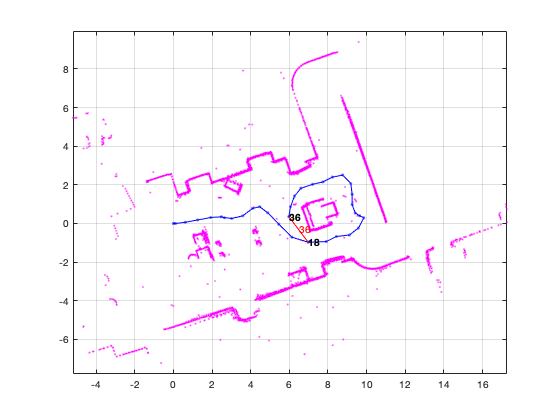

firstTimeLCDetected = false;

figure;
for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end
    % visualize the first detected loop closure, if you want to see the
    % complete map building process, remove the if condition below
    if optimizationInfo.IsPerformed && ~firstTimeLCDetected
        show(slamAlg, 'Poses', 'off');
        hold on;
        show(slamAlg.PoseGraph); 
        hold off;
        firstTimeLCDetected = true;
        drawnow
    end
end

title('First loop closure');


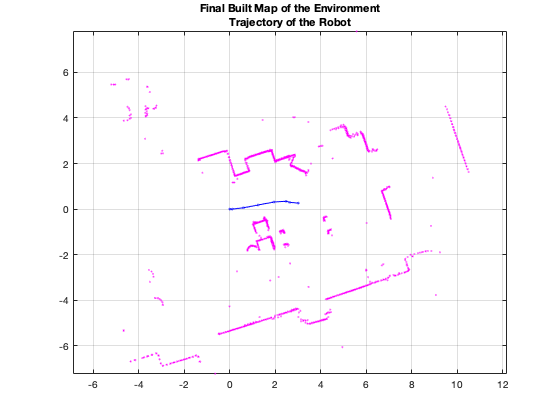

figure
show(slamAlg);
title({'Final Built Map of the Environment', 'Trajectory of the Robot'});

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);

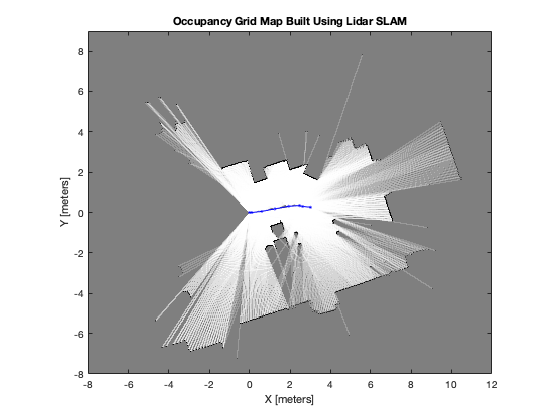

figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');